clc; clear; close all;

# 1D-FC with Gram Inteprolation

Precomputing matrices at high precision for interpolation

# Error Analysis

Doing steps above on sin(pix), will assume computation matrices aren't needed, i.e. they're already given in the FC_data folder.

% fixed parameters
n_lst = [50, 100, 200];
d_lst = 3:8;
%f = @(y) sin(pi*y);
C = 27;

err = zeros(length(d_lst), length(n_lst));

for i = 1%:length(d_lst)
    d = d_lst(i);

    load(['FC_data/A_d',num2str(d),'_C', num2str(C), '.mat']);
    load(['FC_data/Q_d',num2str(d),'_C', num2str(C), '.mat']);
    A = double(A);
    Q = double(Q);

    for j = 1%:length(n_lst)
        n = n_lst(j);
        h = 1/(n-1);
        
        x = transpose(linspace(0, 1, n));
        prd = (n+C)*h;
        [fx_cont_coeffs, fcont, ~, ~] = fcont_gram_blend(f(x), d, C, A, Q, Q);

        n_cont = n + C;
        fx_cont_coeffs
        shift_vector = exp(-1i*2*pi*(floor(n_cont/2))*transpose(0:(n_cont-1))/n_cont);

        fx_cont_coeffs = fftshift(fx_cont_coeffs)
        max(abs(n_cont*ifft(fx_cont_coeffs).*shift_vector - fcont), [], 'all')
        
        % x_err = transpose(linspace(0, 1, 20*n));
        % err(i, j) = max(f(x_err) - FFT_compute_func(fx_cont_coeffs, prd, x_err));
    end
end

fx_cont_coeffs =    0.2683 + 0.0000i
  -0.1626 - 0.3561i
   0.0193 - 0.0222i
   0.0013 + 0.0004i
  -0.0010 - 0.0072i
   0.0087 - 0.0056i
   0.0092 + 0.0059i
  -0.0014 + 0.0099i
  -0.0082 + 0.0024i
  -0.0045 - 0.0052i


fx_cont_coeffs =    0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 + 0.0000i
  -0.0000 - 0.0000i
   0.0000 - 0.0000i
   0.0000 + 0.0000i
  -0.0000 - 0.0000i


ans = 2.1928e-14

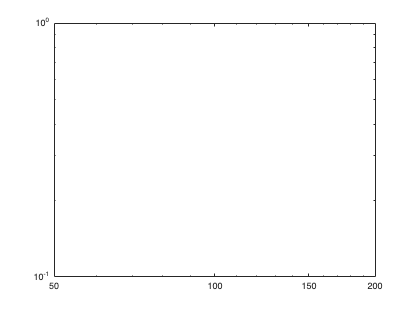

err
figure;
loglog(n_lst, err);


log2(err(:, 1:end-1) ./err(:, 2:end))